# Cell array (異質矩陣)

把不同的資料格式，都存在同一個矩陣裡面

clear
load('materials_L4/ExampleCell.mat')

資料讀進來後，去 matlab 的左邊 workspace，點開 NC 這個變數 (Normal Control group 的意思，對照組的資料)，他是一個 31x7 的 cell array (所以他仍是 array, 但他多加了個 cell ，就可以儲存不同格式的資料)。

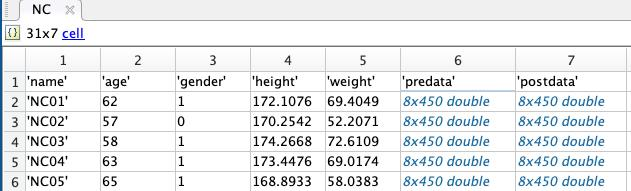

可以看到，每一個 cell，他都可以存不同格式的資料，例如 {1,1} 是 string, {2,2} 是 dobule, {2, 6} 甚至是 8x450 的 2-d array

我們如果把 {2, 6} 這一個點兩下，就可以看到他存的真的是 2-d array

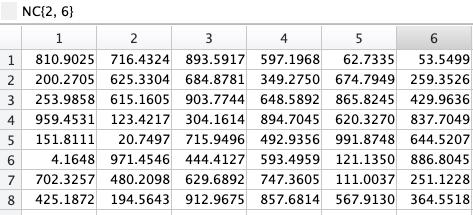

所以，乍看之下，這蠻像 table 的，但差別在，他沒有欄位名稱的概念，而是用第一個 row 來當欄位名稱。

那，接下來，來講如何建立這個 cell array

## Creat a Cell array

% 先宣告空 array
data = {} % 建立空 cell


data =

  0×0 empty cell array



data = cell(4,1) % 建立 4x1 的 cell array

data = 4×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}



% 把每個 cell 塞入
data{1} = 'NC01';
data{2} = 62;
data{3} = rand(8, 450); % number array
data{4} = {16, '%task onset'};

data

data = 4×1 cell array
    {'NC01'      }
    {[        62]}
    {8×450 double}
    {1×2   cell  }
